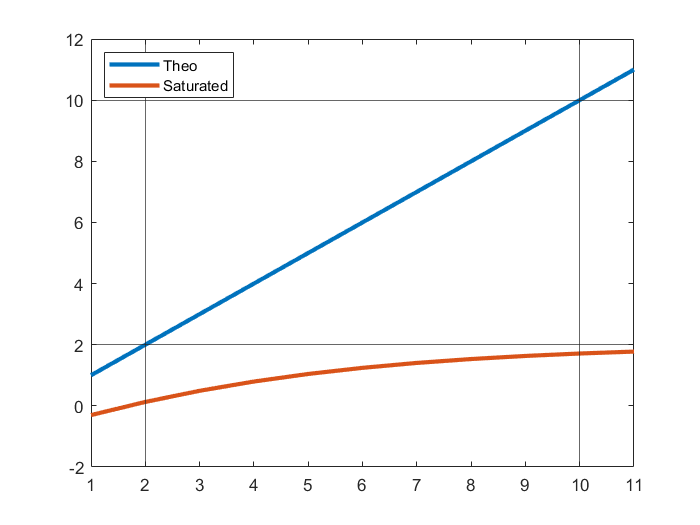

clear
clc
close all
lw = 2.5; % line width

ts = 1;
x_min = 1;
x_max = 11;
amp = 8;
simin(:, 2) = x_min:ts:x_max;
stop_time = length(simin)*ts;
simin(:, 1) = 0:ts:stop_time-ts;

max_v = 10;
min_v = 2;

in = Simulink.SimulationInput('test_saturation_simulink');
out = sim(in);

figure()
plot(simin(:,2), simin(:,2), 'LineWidth',lw);
hold on
plot(simin(:,2), out.result.Data(1:end-1), 'LineWidth', lw)
legend('Theo', 'Saturated', 'location', 'northwest')
yline([min_v max_v],'HandleVisibility','off')
xline([min_v max_v],'HandleVisibility','off')